# Lab7

dt = 0.01;
df = dt;
t = -10 : dt : 10;
f = -15 : df : 15;

## Esercizio 1 (i)

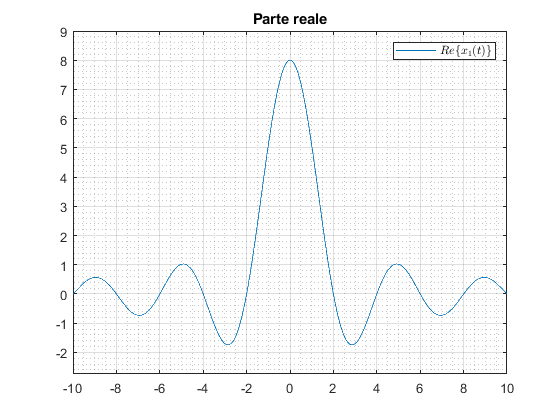

x1 = 8 * sinc(t / 2);
rappresentaUnSegnale(t, x1, 'x_{1}(t)');

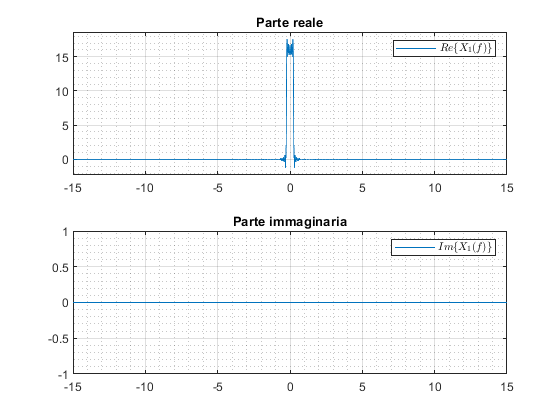

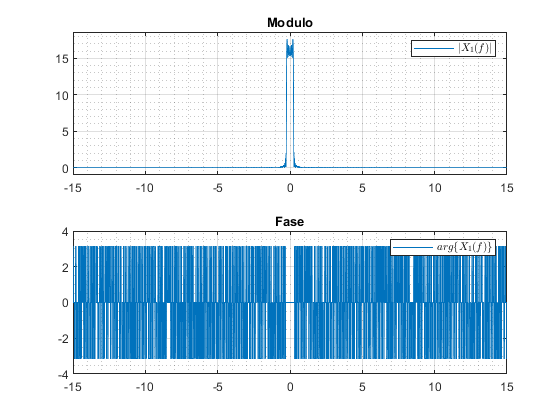

X1 = trasformataDiFourier(t, x1, f);
rappresentaUnSegnale(f, X1, 'X_{1}(f)');

## Esercizio 1 (ii - iii - iv)

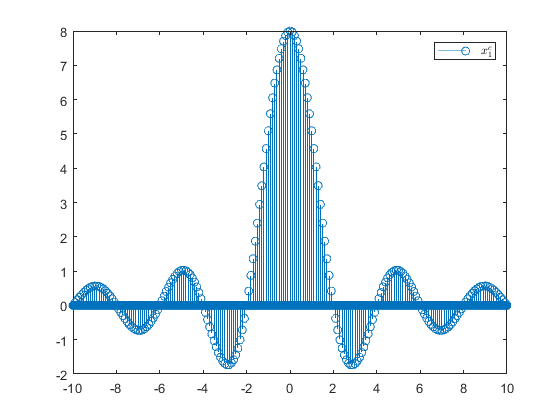

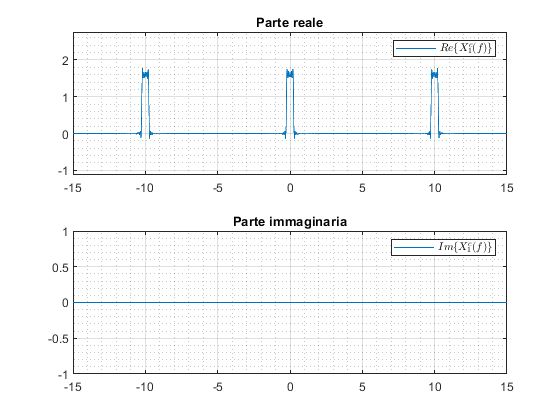

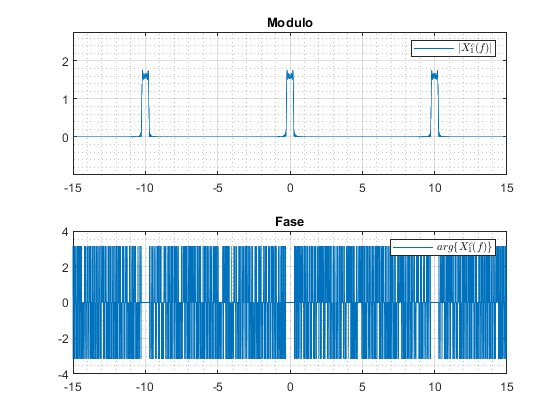

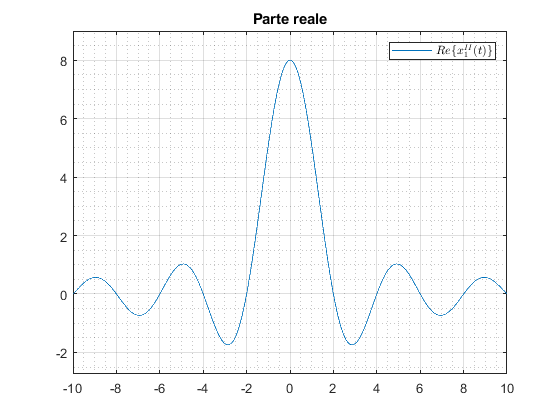

L'energia dell'errore di ricostruzione del segnale x1 con l'interpolatore ideale è: 8.656558e-06

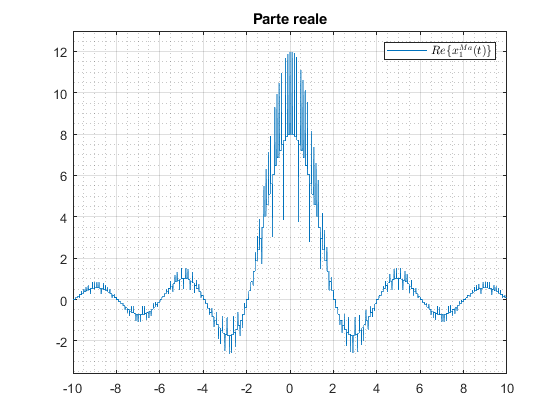

L'energia dell'errore di ricostruzione del segnale x1 con il mantenitore ZOH è: 3.453679e+00

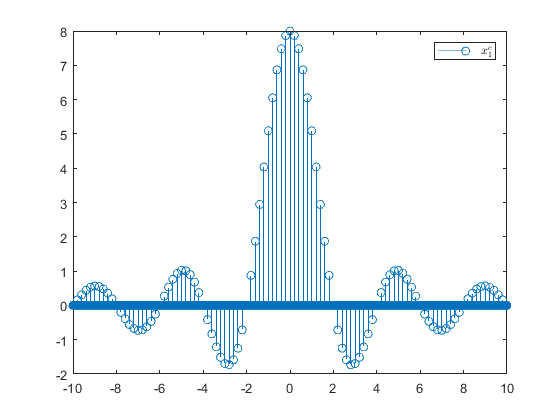

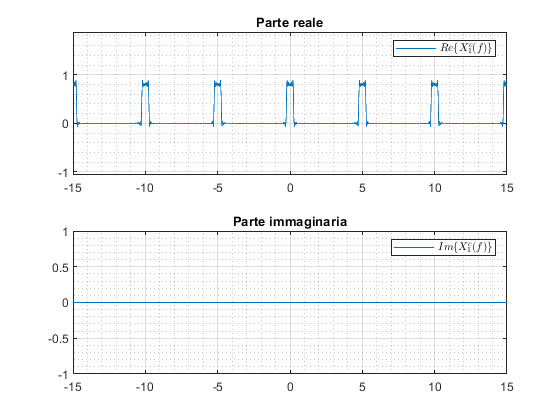

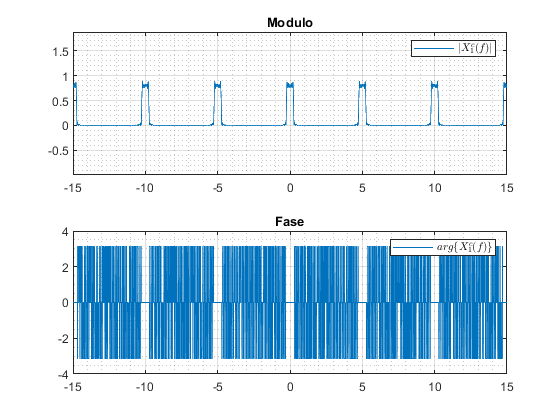

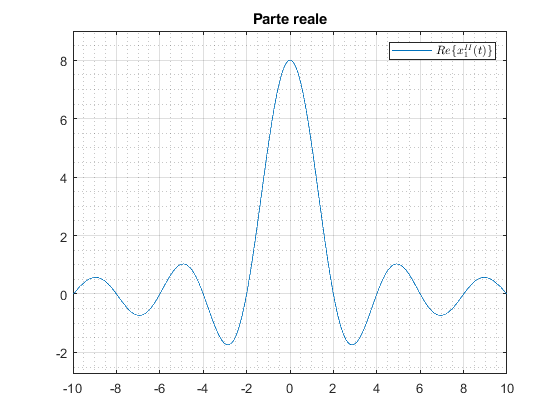

L'energia dell'errore di ricostruzione del segnale x1 con l'interpolatore ideale è: 6.745651e-05

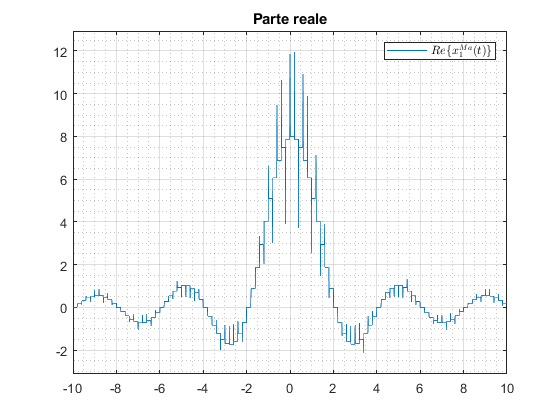

L'energia dell'errore di ricostruzione del segnale x1 con il mantenitore ZOH è: 2.833513e+00

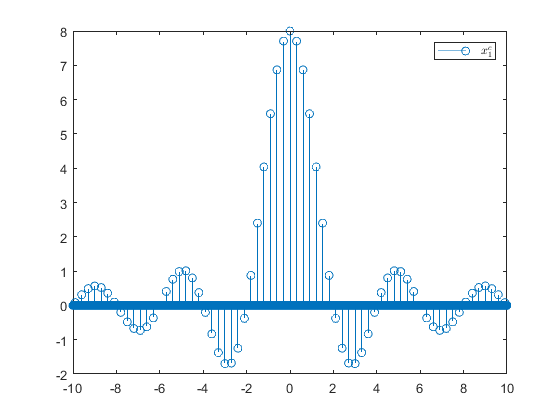

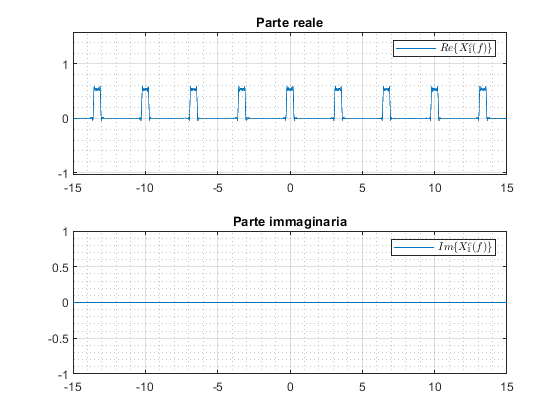

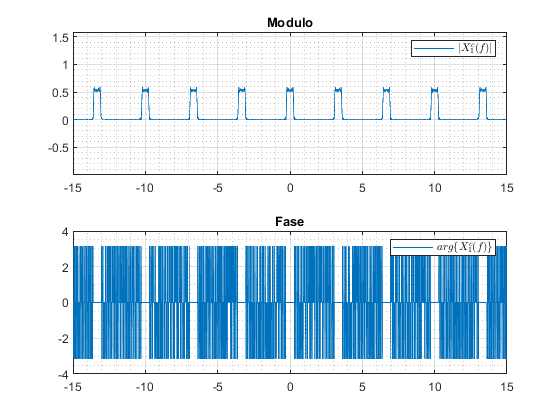

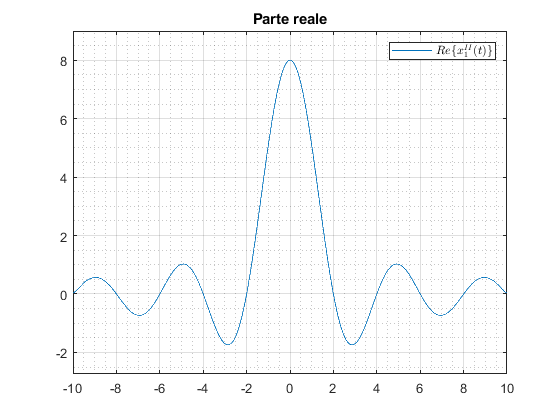

L'energia dell'errore di ricostruzione del segnale x1 con l'interpolatore ideale è: 1.280855e-04

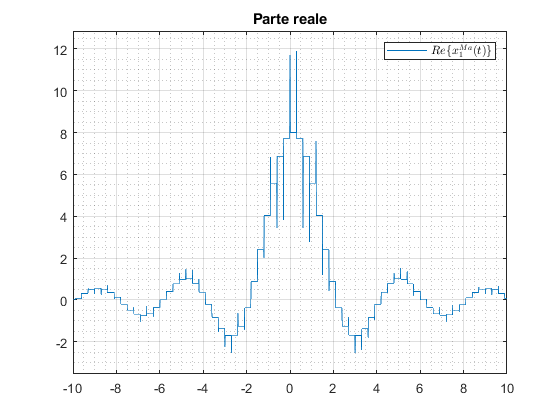

L'energia dell'errore di ricostruzione del segnale x1 con il mantenitore ZOH è: 3.909112e+00

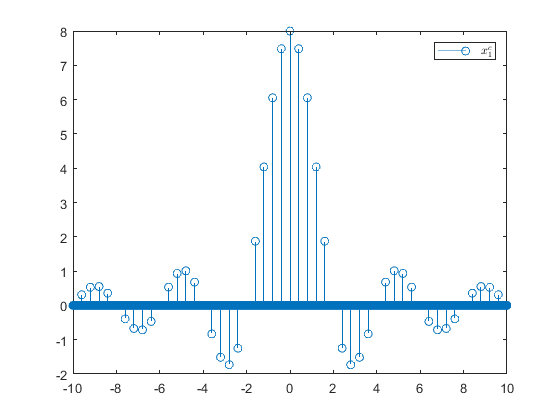

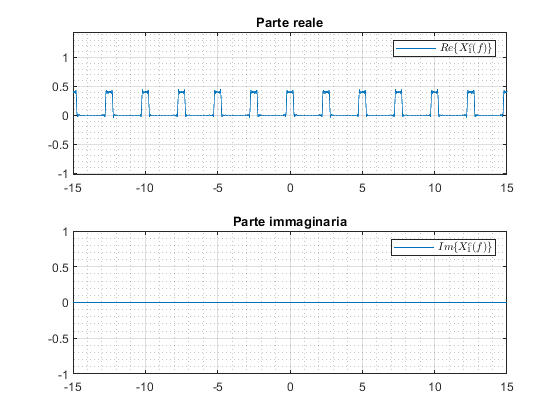

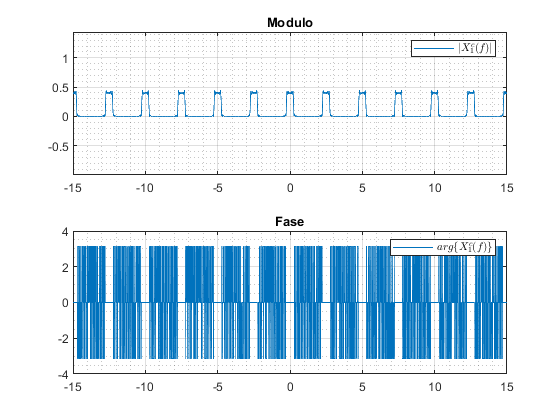

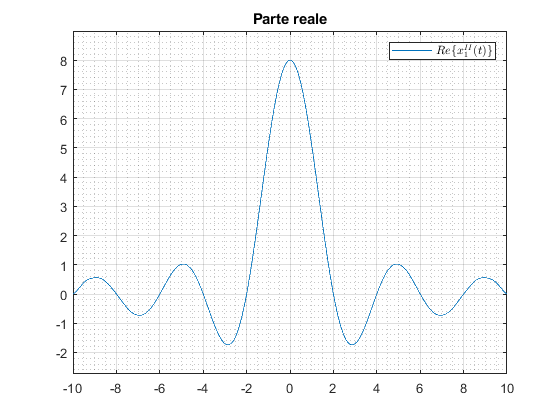

L'energia dell'errore di ricostruzione del segnale x1 con l'interpolatore ideale è: 5.194869e-04

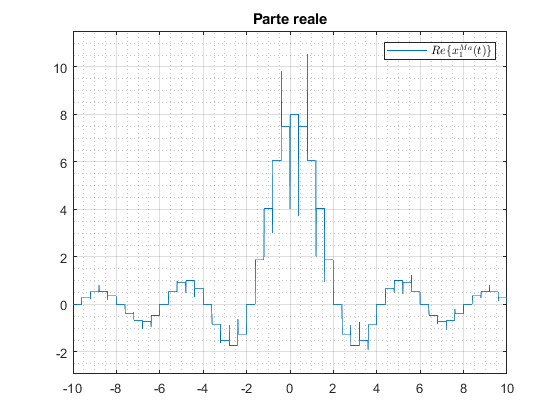

L'energia dell'errore di ricostruzione del segnale x1 con il mantenitore ZOH è: 5.853097e+00

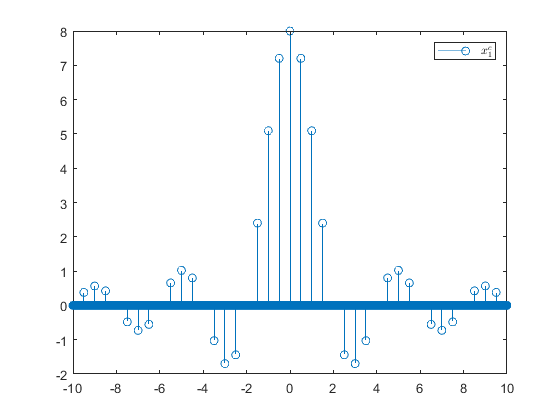

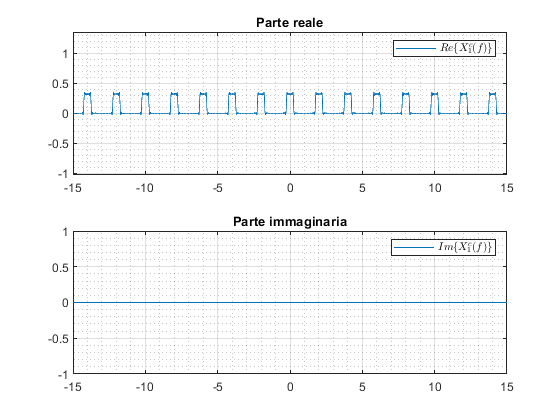

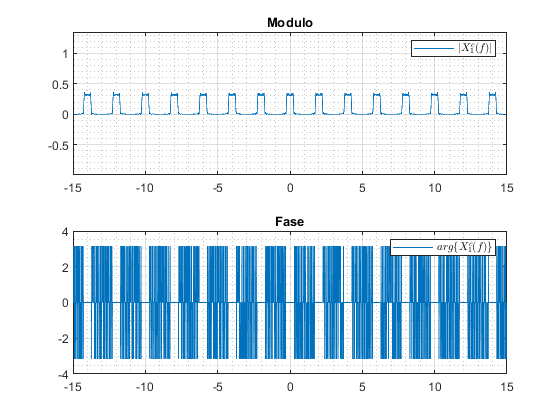

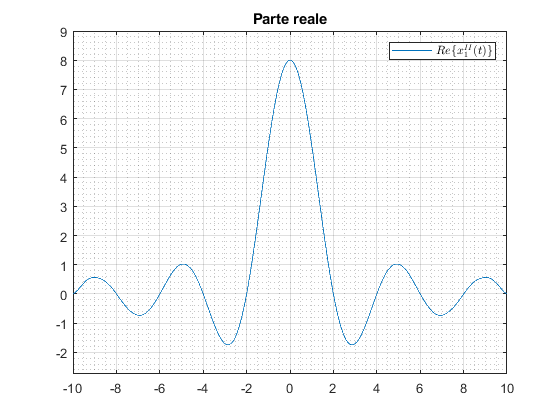

L'energia dell'errore di ricostruzione del segnale x1 con l'interpolatore ideale è: 1.001254e-03

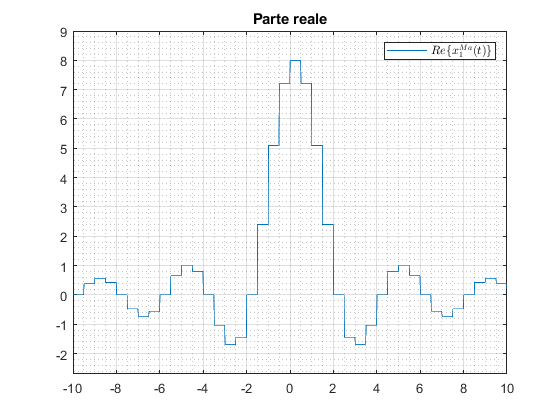

L'energia dell'errore di ricostruzione del segnale x1 con il mantenitore ZOH è: 7.977262e+00

for tc = 10 * dt : 10 * dt : 50 * dt
	x1c = campionatore(t, x1, tc^-1);
	figure, stem(t, x1c), legend('$x_{1}^{c}$', 'Interpreter', 'latex');
	X1c = trasformataDiFourier(t, x1c, f);
	rappresentaUnSegnale(f, X1c, 'X_{1}^{c}(f)');
	x1II = interpolatoreIdeale(t, x1, tc^-1);
	rappresentaUnSegnale(t, x1II, 'x_{1}^{II}(t)');
	fprintf('L''energia dell''errore di ricostruzione del segnale x1 con l''interpolatore ideale è: %d', energia(t, x1 - x1II));
	x1Ma = mantenitore(t, x1, tc^-1);
	rappresentaUnSegnale(t, x1Ma, 'x_{1}^{Ma}(t)');
	fprintf('L''energia dell''errore di ricostruzione del segnale x1 con il mantenitore ZOH è: %d', energia(t, x1 - x1Ma));
end

## Esercizio 2

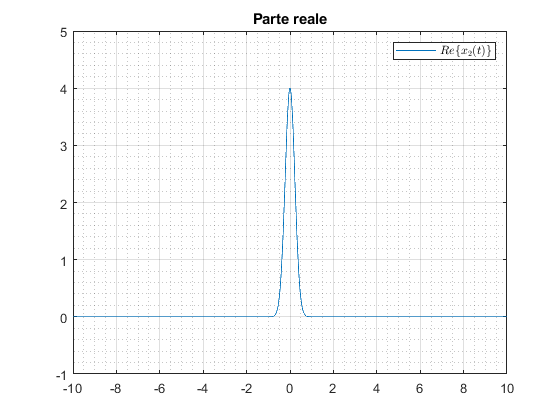

x2 = 4 * exp(-10 * t.^2);
rappresentaUnSegnale(t, x2, 'x_{2}(t)');

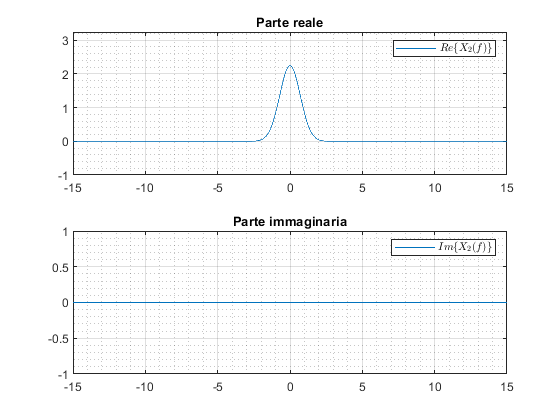

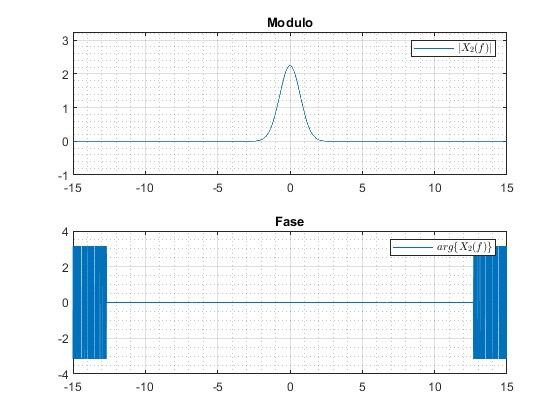

X2 = trasformataDiFourier(t, x2, f);
rappresentaUnSegnale(f, X2, 'X_{2}(f)');

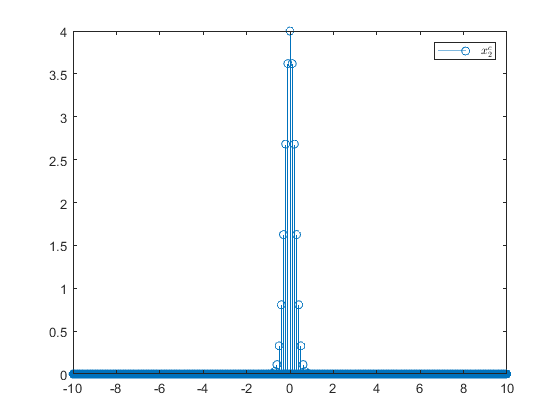

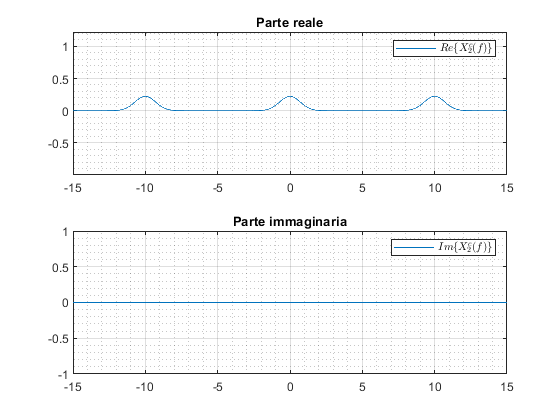

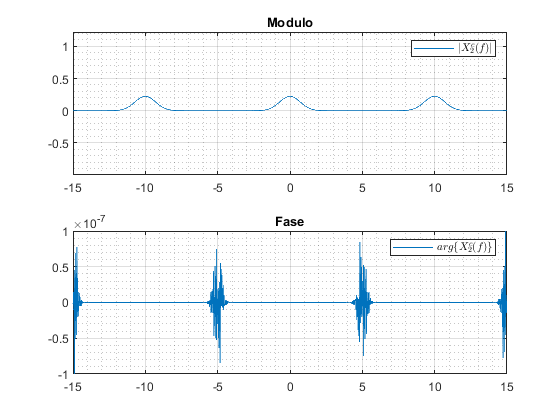

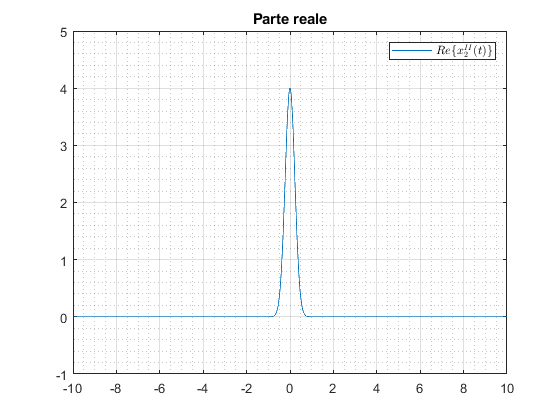

L'energia dell'errore di ricostruzione del segnale x2 con l'interpolatore ideale è: 2.991424e-22

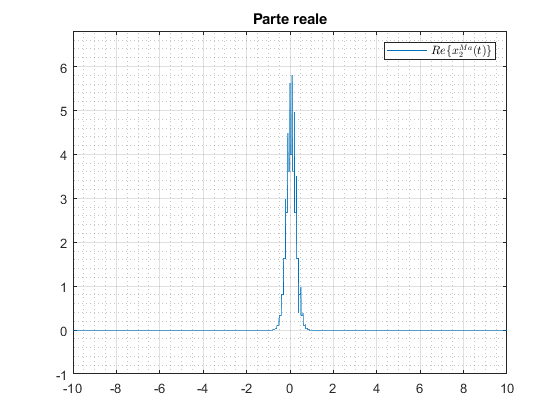

L'energia dell'errore di ricostruzione del segnale x2 con il mantenitore ZOH è: 3.610798e-01

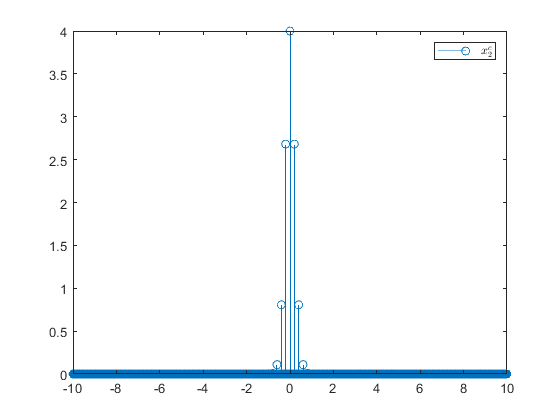

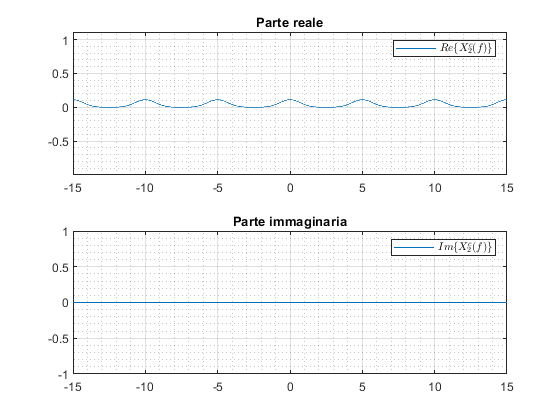

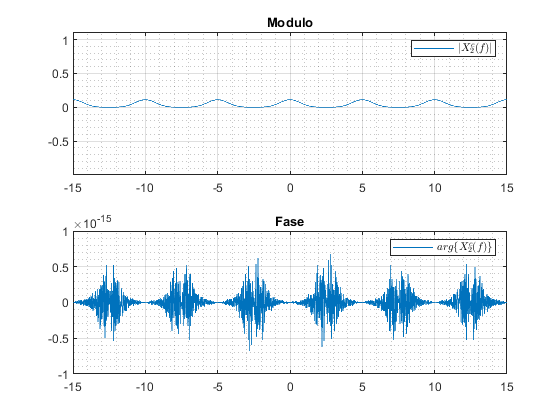

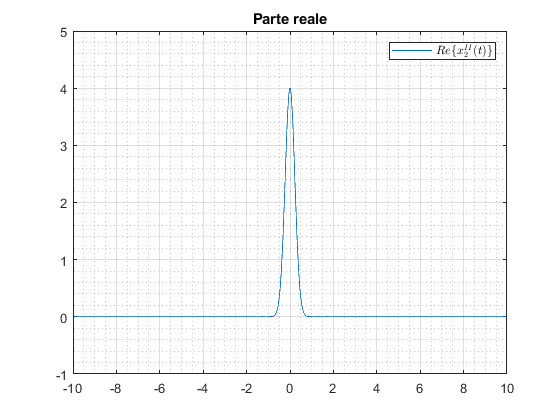

L'energia dell'errore di ricostruzione del segnale x2 con l'interpolatore ideale è: 7.720497e-06

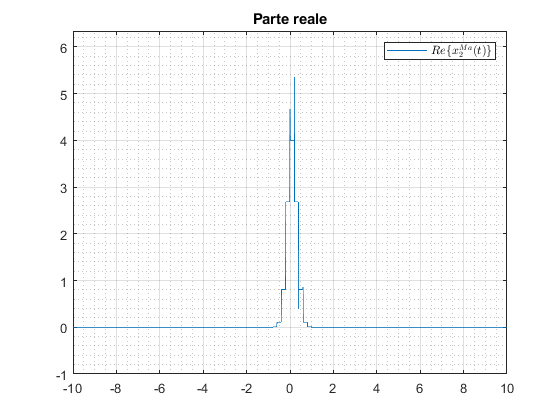

L'energia dell'errore di ricostruzione del segnale x2 con il mantenitore ZOH è: 8.421803e-01

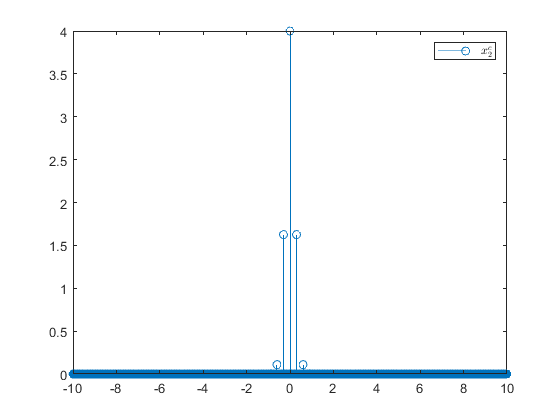

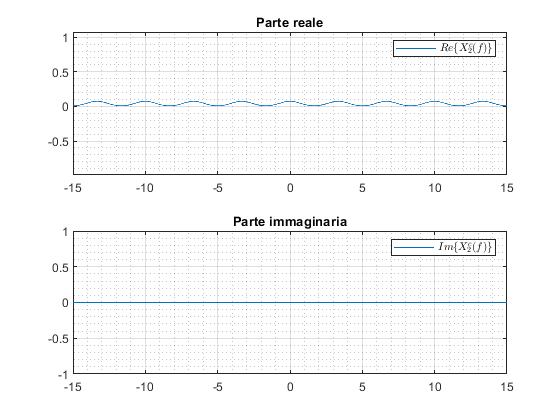

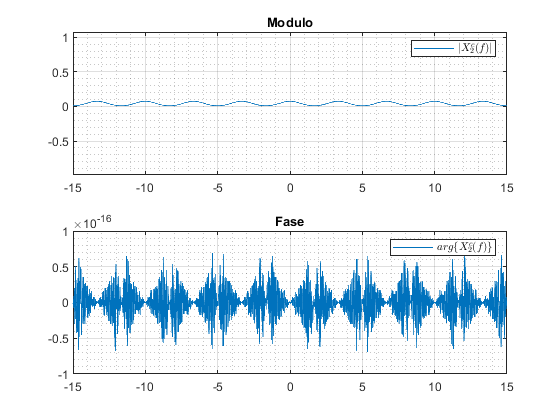

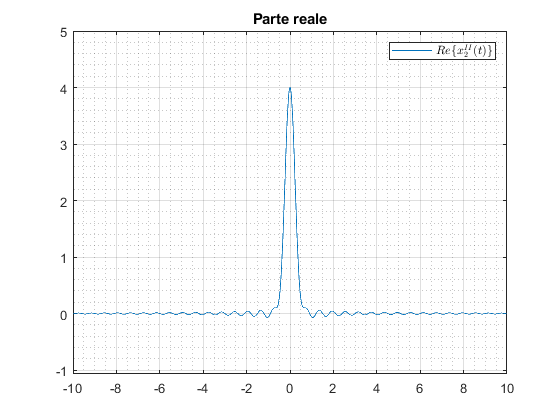

L'energia dell'errore di ricostruzione del segnale x2 con l'interpolatore ideale è: 1.091959e-02

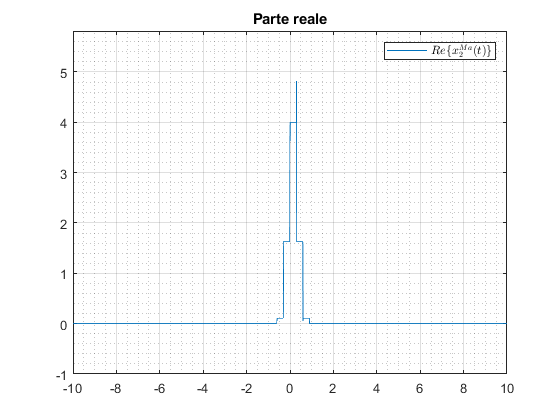

L'energia dell'errore di ricostruzione del segnale x2 con il mantenitore ZOH è: 1.746285e+00

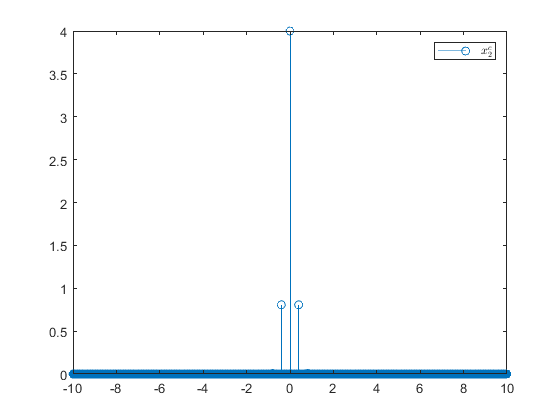

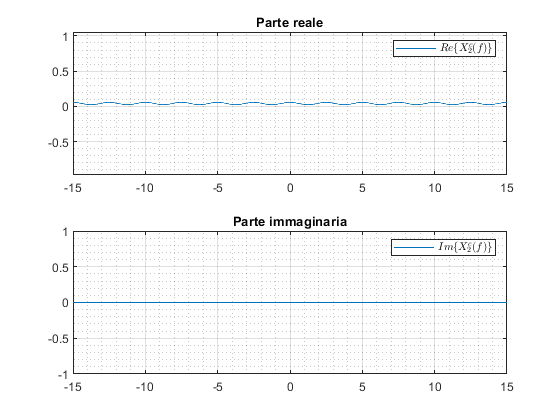

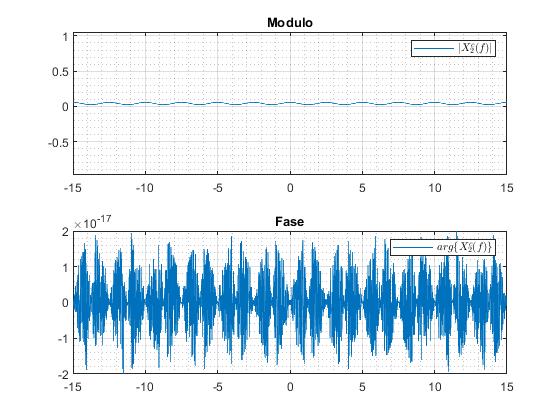

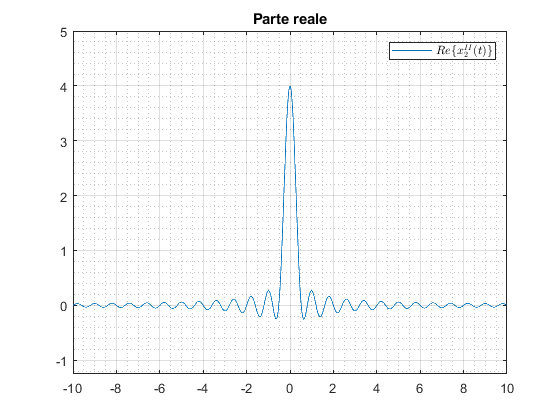

L'energia dell'errore di ricostruzione del segnale x2 con l'interpolatore ideale è: 1.556704e-01

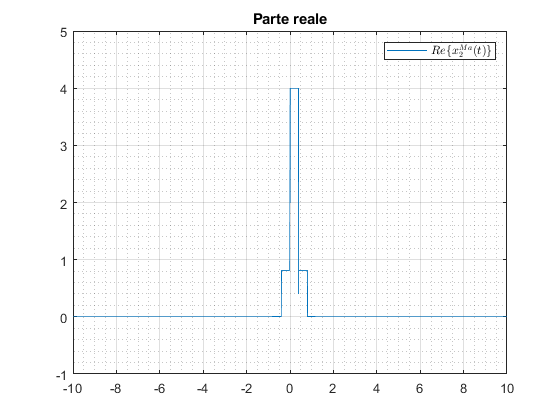

L'energia dell'errore di ricostruzione del segnale x2 con il mantenitore ZOH è: 3.086219e+00

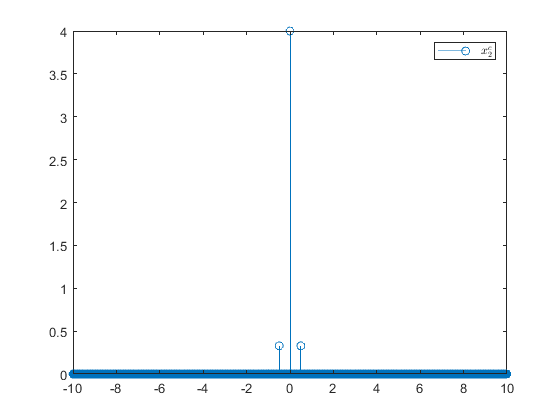

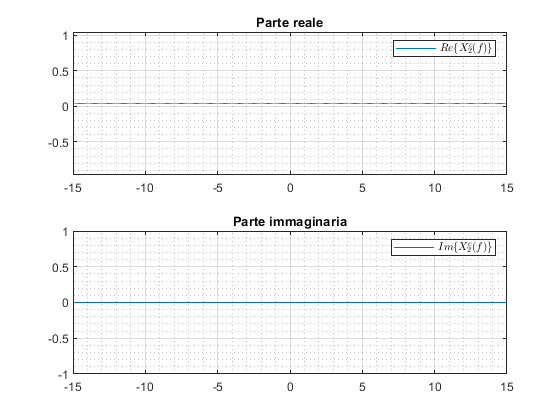

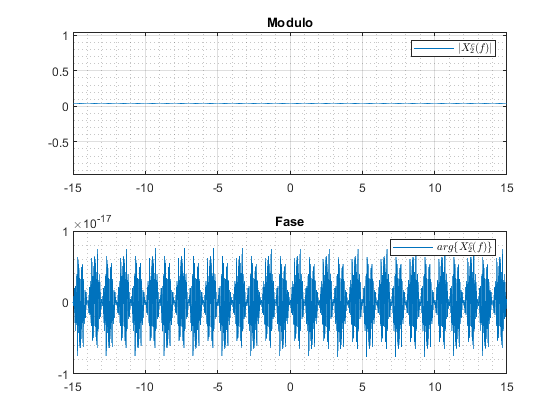

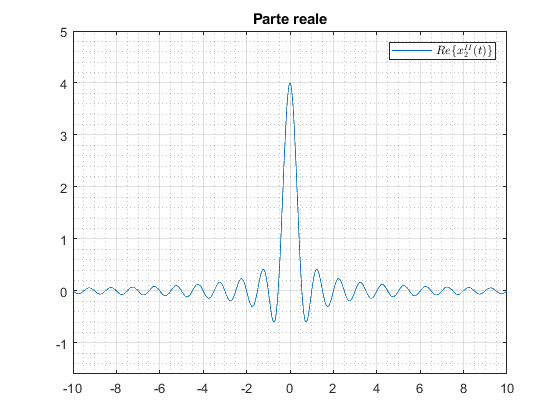

L'energia dell'errore di ricostruzione del segnale x2 con l'interpolatore ideale è: 5.715345e-01

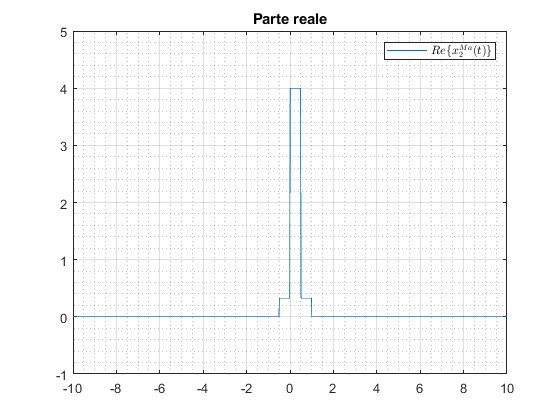

L'energia dell'errore di ricostruzione del segnale x2 con il mantenitore ZOH è: 4.904593e+00

for tc = 10 * dt : 10 * dt : 50 * dt
	x2c = campionatore(t, x2, tc^-1);
	figure, stem(t, x2c), legend('$x_{2}^{c}$', 'Interpreter', 'latex');
	X2c = trasformataDiFourier(t, x2c, f);
	rappresentaUnSegnale(f, X2c, 'X_{2}^{c}(f)');
	x2II = interpolatoreIdeale(t, x2, tc^-1);
	rappresentaUnSegnale(t, x2II, 'x_{2}^{II}(t)');
	fprintf('L''energia dell''errore di ricostruzione del segnale x2 con l''interpolatore ideale è: %d', energia(t, x2 - x2II));
	x2Ma = mantenitore(t, x2, tc^-1);
	rappresentaUnSegnale(t, x2Ma, 'x_{2}^{Ma}(t)');
	fprintf('L''energia dell''errore di ricostruzione del segnale x2 con il mantenitore ZOH è: %d', energia(t, x2 - x2Ma));
end

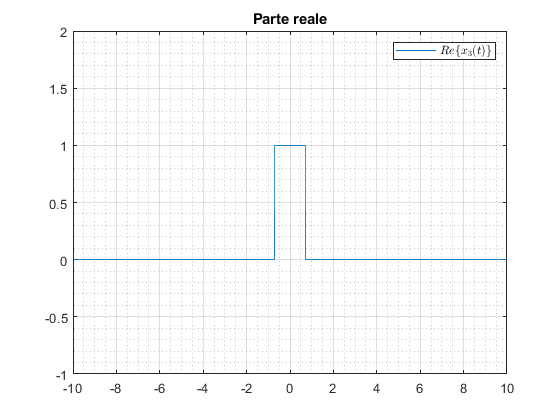

x3 = rect(t / sqrt(2));
rappresentaUnSegnale(t, x3, 'x_{3}(t)');

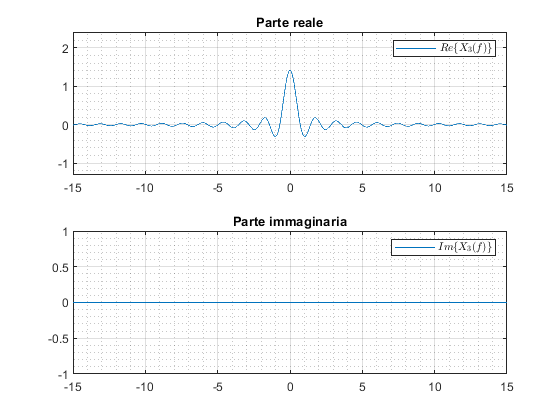

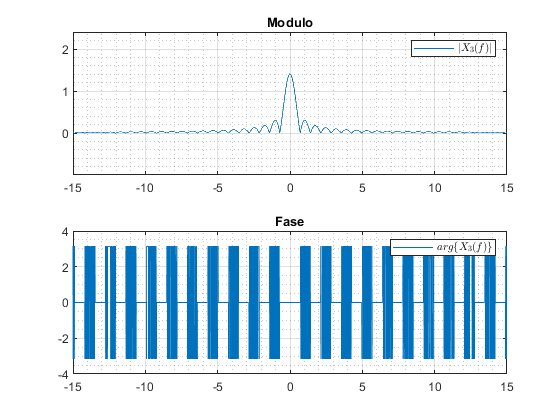

X3 = trasformataDiFourier(t, x3, f);
rappresentaUnSegnale(f, X3, 'X_{3}(f)');

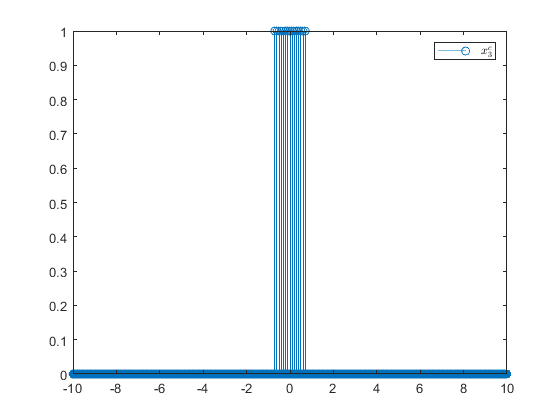

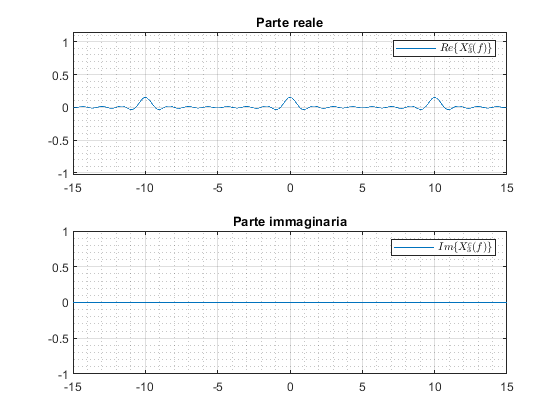

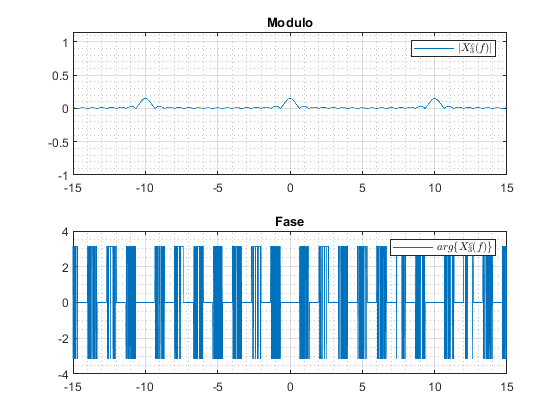

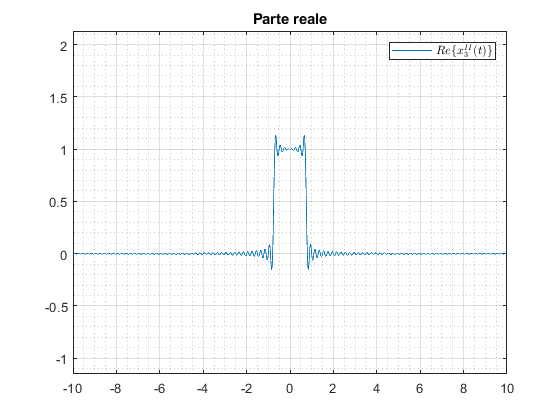

L'energia dell'errore di ricostruzione del segnale x3 con l'interpolatore ideale è: 6.751619e-02

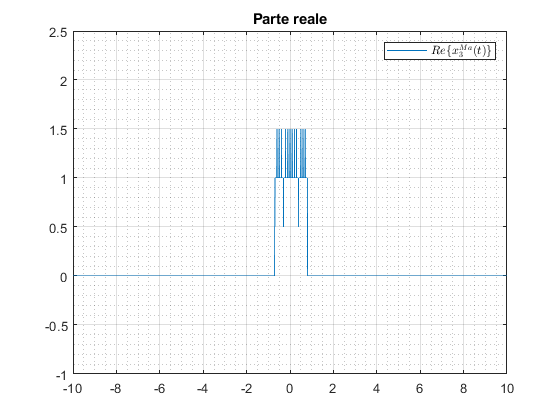

L'energia dell'errore di ricostruzione del segnale x3 con il mantenitore ZOH è: 1.375000e-01

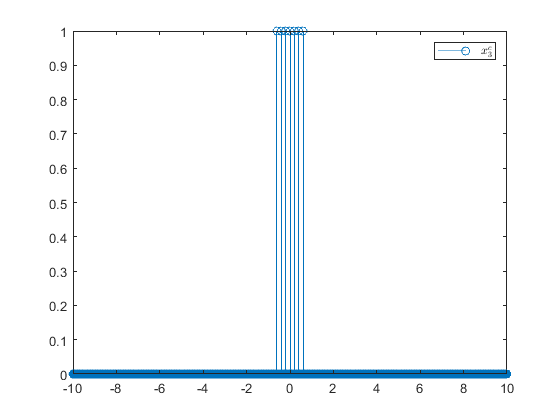

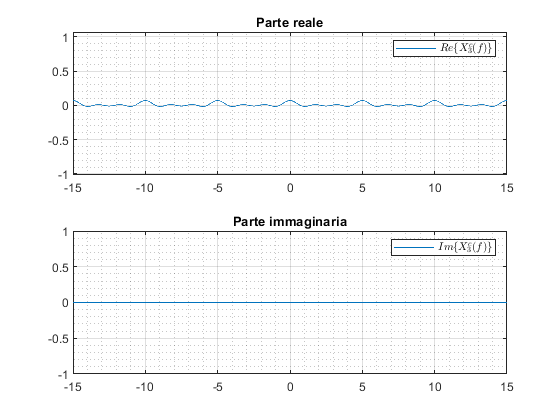

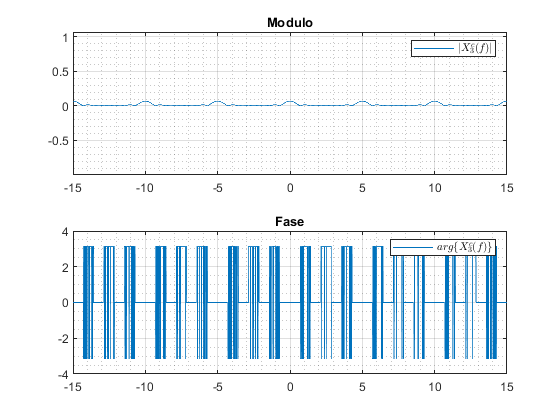

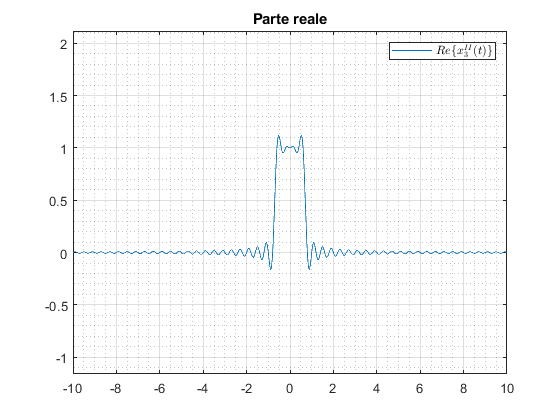

L'energia dell'errore di ricostruzione del segnale x3 con l'interpolatore ideale è: 4.350588e-02

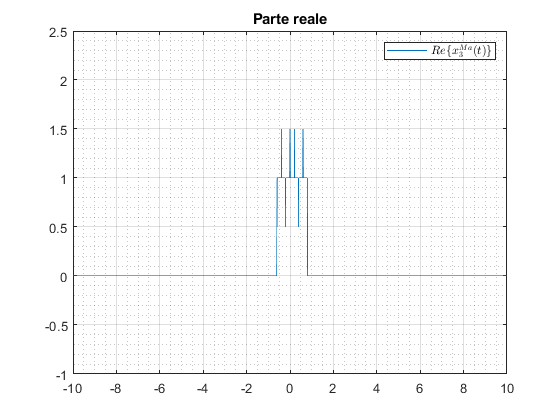

L'energia dell'errore di ricostruzione del segnale x3 con il mantenitore ZOH è: 2.175000e-01

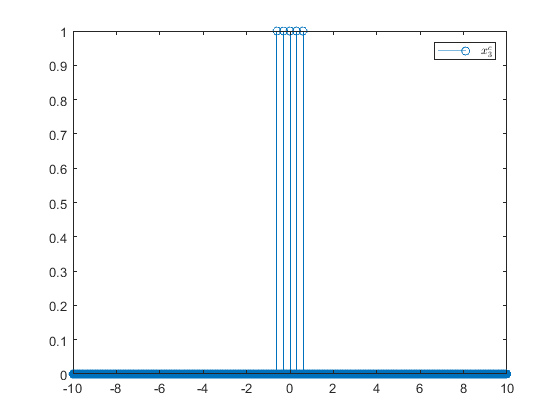

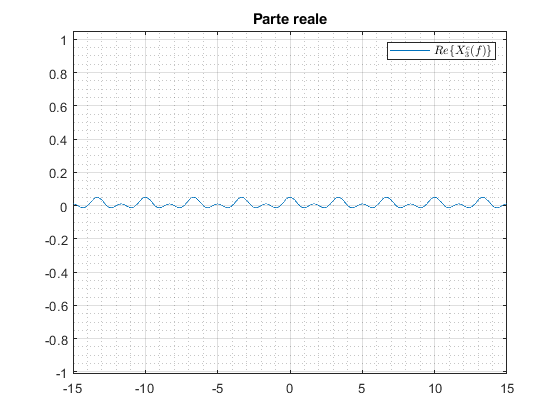

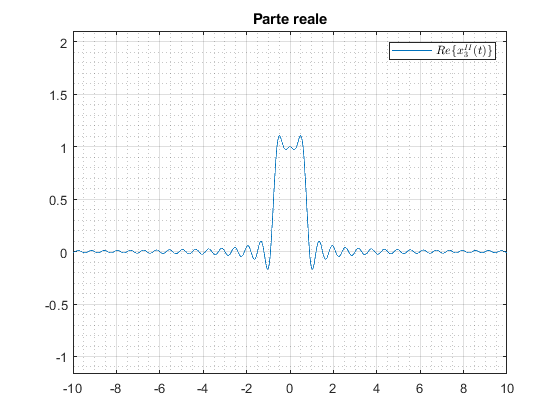

L'energia dell'errore di ricostruzione del segnale x3 con l'interpolatore ideale è: 8.681191e-02

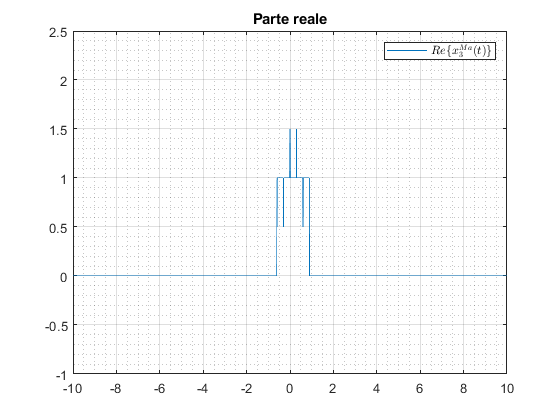

L'energia dell'errore di ricostruzione del segnale x3 con il mantenitore ZOH è: 3.025000e-01

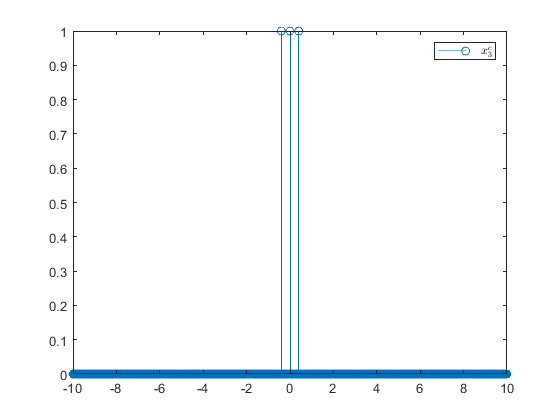

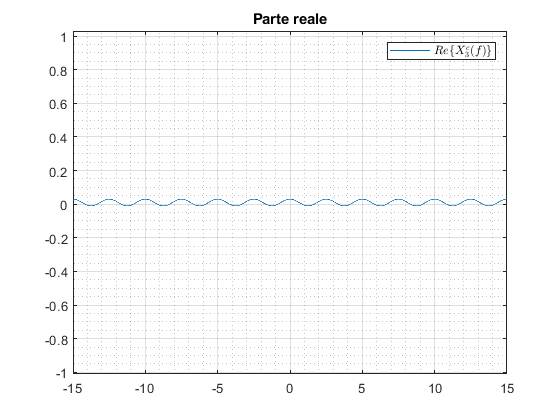

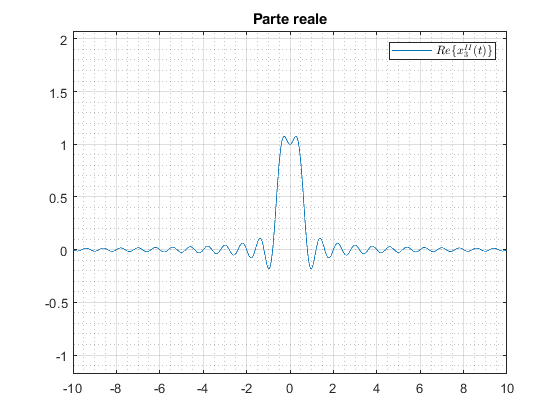

L'energia dell'errore di ricostruzione del segnale x3 con l'interpolatore ideale è: 1.330045e-01

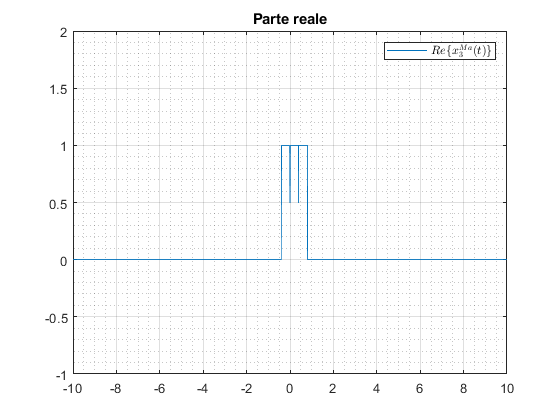

L'energia dell'errore di ricostruzione del segnale x3 con il mantenitore ZOH è: 4.075000e-01

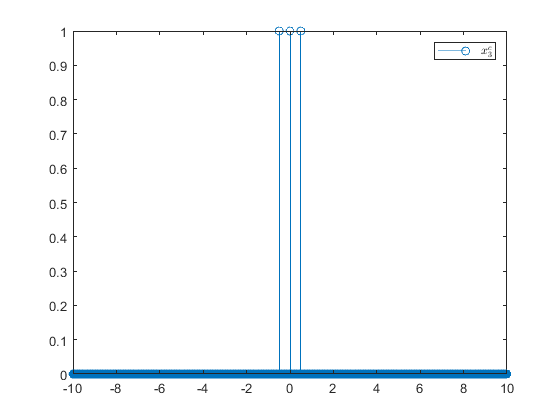

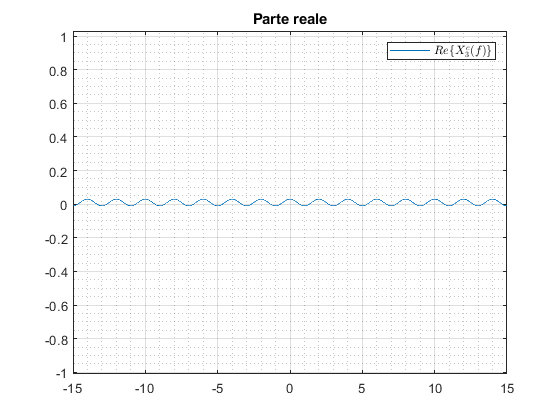

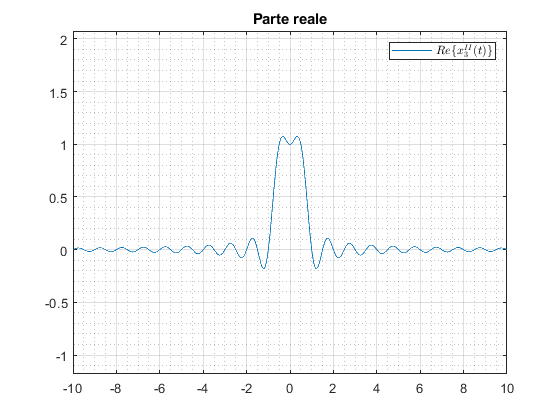

L'energia dell'errore di ricostruzione del segnale x3 con l'interpolatore ideale è: 1.291178e-01

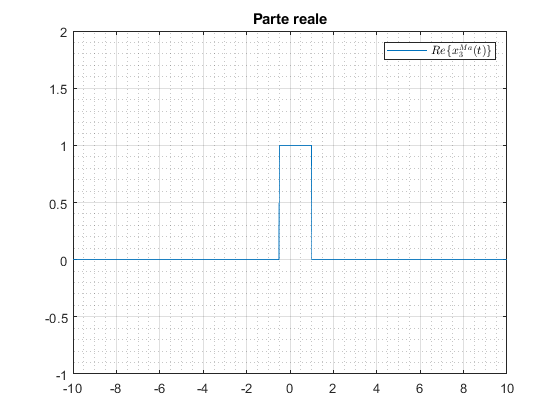

L'energia dell'errore di ricostruzione del segnale x3 con il mantenitore ZOH è: 4.950000e-01

for tc = 10 * dt : 10 * dt : 50 * dt
	x3c = campionatore(t, x3, tc^-1);
	figure, stem(t, x3c), legend('$x_{3}^{c}$', 'Interpreter', 'latex');
	X3c = trasformataDiFourier(t, x3c, f);
	rappresentaUnSegnale(f, X3c, 'X_{3}^{c}(f)');
	x3II = interpolatoreIdeale(t, x3, tc^-1);
	rappresentaUnSegnale(t, x3II, 'x_{3}^{II}(t)');
	fprintf('L''energia dell''errore di ricostruzione del segnale x3 con l''interpolatore ideale è: %d', energia(t, x3 - x3II));
	x3Ma = mantenitore(t, x3, tc^-1);
	rappresentaUnSegnale(t, x3Ma, 'x_{3}^{Ma}(t)');
	fprintf('L''energia dell''errore di ricostruzione del segnale x3 con il mantenitore ZOH è: %d', energia(t, x3 - x3Ma));
end